# Beta Stim Explore 4-6-2016 - all subjects 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaBase = [];
anovaBetaSID = {};
betaDistTotal = [];
        
    t3Total = [];
    t2Total = [];
    t1Total = [];
    tBTotal = [];
    Btotal = [];
    

answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

for i = 2:length(SIDS)
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            
    end
    
    
    load tTemp.mat
    subjid = sid;
    if (strcmp(sid,'0b5a2ePlayback'))
        load(fullfile(getSubjDir('0b5a2e'), 'trodes.mat'));
    else
        load(fullfile(getSubjDir(subjid),'trodes.mat'))
    end
    
    
    locs = Grid;
    
    
    gridSize = 64;
    
    % calculate distances
    
    distances = matrixDist(locs);
    
    
    betaDist = channelExtract(distances,betaChan);
    stim1Dist = channelExtract(distances,stims(1));
    stim2Dist = channelExtract(distances,stims(2));
    
    
    chans = [1:64];
    
    % using all channels
    %     logChans = chans;
    %     logChans(stims) = 0;
    %     logChans = logical(logChans);
    
    % using good channels add in goods - 4/6/2016 - DJC
    logChans = chans;
    logChans(goods) = 0;
    logChans = ~logical(logChans);
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % total cell responses
    rB = {};
    r12 = {};
    r34 = {};
    r5 = {};
    
    tBmat =[];
    t1mat = [];
    t2mat = [];
    t3mat = [];

    
    switch(answer)
        case 'zscore'
            dataForAnova = ZscoredDataForAnova;
        case 'raw'
            dataForAnova = dataForAnova;
    end
    
    
    for chan = chans
        % cells, rather than stacked, of responses for given num stimuli
        tempBaseTotal = {};
        tempResp1Total = {};
        tempResp2Total = {};
        tempResp3Total = {};
        tempRespNull = {};
        
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        
        if chan~=stims
            for i = 1:numTypes
                
                if i ~= nullType
                    tempMag = dataForAnova{chan}{i}{1};
                    tempLabel = dataForAnova{chan}{i}{2};
                    tempKeeps = dataForAnova{chan}{i}{3};
                    
                    tempBase = tempMag(tempLabel(tempKeeps)==0);
                    tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                    tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                    tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                    
                    tempBaseTotal{i} =  tempBase;
                    tempResp1Total{i} =  tempResp1;
                    tempResp2Total{i} =  tempResp2;
                    tempResp3Total{i} =  tempResp3;
                    
                    tB = [tB tempBase];
                    t1 = [t1 tempResp1];
                    t2 = [t2 tempResp2];
                    t3 = [t3 tempResp3];
                    
                elseif i == nullType && strcmp(sid,'ecb43e') == 0
                    tempMag = dataForAnova{chan}{i}{1};
                    tempLabel = dataForAnova{chan}{i}{2};
                    tempKeeps = dataForAnova{chan}{i}{3};
                    
                    tempBase = tempMag(tempLabel(tempKeeps)==0);
                    tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                    
                    tempRespNull{i} = tempResp1;
                    
                end
            end
            
            
            tBMean = mean(tB);
            t1Mean = mean(t1);
            t2Mean = mean(t2);
            t3Mean = mean(t3);
            
            tBmat(chan) =tBMean;
            t1mat(chan) = t1Mean;
            t2mat(chan) = t2Mean;
            t3mat(chan) = t3Mean;
            
            rB{chan} = tempBaseTotal;
            r12{chan} = tempResp1Total;
            r34{chan} = tempResp2Total;
            r5{chan} = tempResp3Total;
            
            
        end
    end
    
    t3log = t3mat(logChans);
    t2log = t2mat(logChans);
    t1log = t1mat(logChans);
    tBlog = tBmat(logChans);
    
    t3Total = [t3Total t3log];
    t2Total = [t2Total t2log];
    t1Total = [t1Total t1log];
    tBTotal = [tBTotal tBlog];
    Btotal = [Btotal betaDist(logChans)];
    
    %Do a scatter plot of response vs. distance - > 5 stims
    
%     figure
%     scatter(betaDist(logChans),t3mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     %     figure
%     %     scatter(betaDist(logChans),latencyResp(logChans))
%     %     title([sid,'CCEP latency vs. distance from beta channel'])
%     %
%     figure
%     [f,gof] = fit(betaDist(logChans)',t3mat(logChans)','exp1');
%     plot(f,betaDist(logChans),t3mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     gof
%     
%     figure
%     [f,gof] = fit(betaDist(logChans)',t3mat(logChans)','poly3');
%     plot(f,betaDist(logChans),t3mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     gof
%     
%     % Do a scatter plot of response vs. distance -  3,4 stims
%     
%     figure
%     scatter(betaDist(logChans),t2mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     %     figure
%     %     scatter(betaDist(logChans),latencyResp(logChans))
%     %     title([sid,'CCEP latency vs. distance from beta channel'])
%     %
%     figure
%     [f,gof] = fit(betaDist(logChans)',t2mat(logChans)','exp1','Robust','LAR')
%     plot(f,betaDist(logChans),t2mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     gof
%     
%     figure
%     [f,gof] = fit(betaDist(logChans)',t2mat(logChans)','poly3');
%     plot(f,betaDist(logChans),t2mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     gof
%     
%     %Do a scatter plot of response vs. distance - 1,2 stims
%     
%     figure
%     scatter(betaDist(logChans),t1mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     %     figure
%     %     scatter(betaDist(logChans),latencyResp(logChans))
%     %     title([sid,'CCEP latency vs. distance from beta channel'])
%     %
%     figure
%     [f,gof] = fit(betaDist(logChans)',t1mat(logChans)','exp1');
%     plot(f,betaDist(logChans),t1mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     gof
%     
%     figure
%     [f,gof] = fit(betaDist(logChans)',t1mat(logChans)','poly3');
%     plot(f,betaDist(logChans),t1mat(logChans))
%     title([sid,'CCEP magnitude response vs. distance from beta channel'])
%     
%     gof
    
end

sid = d5cd55

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

sid = 0b5a2ePlayback

## Do it in aggregate!

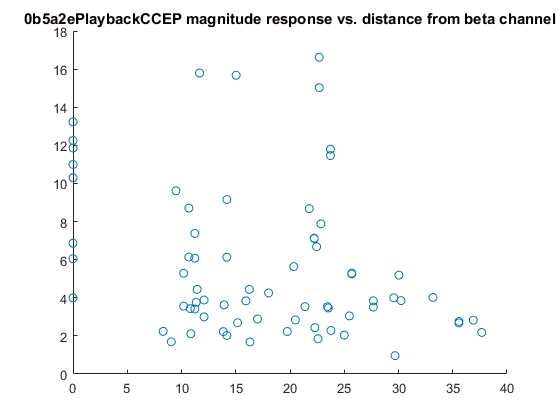

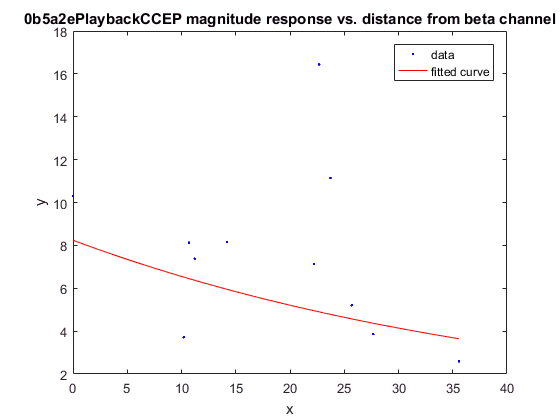

switch (answer)
    case 'zscore'
        figure
        scatter(Btotal,t3Total)
        title(['Aggregated CCEP magnitude response vs. distance from beta channel'])
        
        %
        figure
        [f,gof] = fit(Btotal',t3Total','exp1');
        plot(f,betaDist(logChans),t1mat(logChans))
        title(['Aggregated CCEP magnitude response vs. distance from beta channel'])
end


gof

gof =            sse: 934.6052
       rsquare: 0.1021
           dfe: 68
    adjrsquare: 0.0889
          rmse: 3.7073
